m = 150;
r_domain = linspace(0,2,m);
theta_domain = linspace(0,2*pi,m);
Omega_r = meshgrid(r_domain);
Omega_th = meshgrid(theta_domain)';
[Omega_x,Omega_y] = pol2cart(Omega_th,Omega_r);

% plot(x_domain,y_domain)

syms n r theta x y

n_s = 2*(1:1000) - 1; %Points in the summation at each x,y location

U = zeros(m);

for k = 1:m

    for l = 1:m
%         x = Omega_x(k,l);
%         y = Omega_y(k,l);
%         U(k,l) =  sum(2.^(1-n_s)/(pi.*n_s).*(sqrt(x^2+y^2)).^n_s.*sin(n_s.*atan2(y,x))) + 1/2; 
        r = Omega_r(k,l);
        th = Omega_th(k,l);
        a = 2.^(1-n_s);
        b = pi.*n_s;
        c = r.^n_s;
        d = sin(n_s.*th);
        U(k,l) =  sum(2./(pi.*n_s).*(r/2).^n_s.*sin(n_s.*th)) + 1/2;   
    end
end






% fund_sol = 2^(1-n)/(pi*n)*r^n*sin(n*theta)
% fund_sol(x,y,n) = subs(fund_sol,[r theta n], [sqrt(x^2 + y^2) atan2(y,x) 2*n+1])


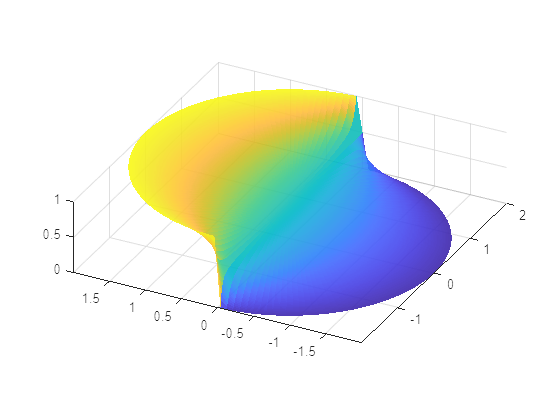

% U_sym = symsum(fund_sol,n,0,20) + 0.5;
% U_fun = matlabFunction(U_sym)

% U_fun_dat = U_fun(Omega_x,Omega_y);

figure
surf(Omega_x,Omega_y,U,'FaceAlpha',0.9, 'EdgeColor','none')

zlim([0 1])
axis equal

view([-63.300 28.806])